# Expand Example 3.29:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Truncation of a sinusoidal signal is illustrated in the figure below.

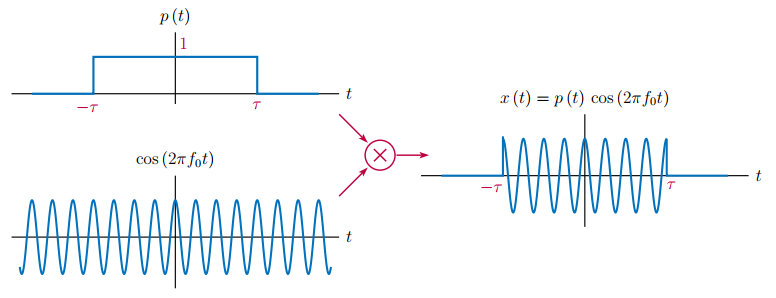

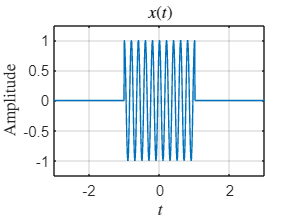

f0 =   5; % Frequency
tau = 1; % Truncation parameter
t = [-3:0.01:3];    % Vector of time instants
x = cos(2*pi*f0*t).*((t>=-tau)&(t<=tau));
f = [-15:0.02:15];  % Vector of frequencies
% Compute the transform
P = @(f) 2*tau*sinc(2*tau*f);
X = 0.5*P(f-f0)+0.5*P(f+f0);
% Graph the signal and the transform
plot(t,x); grid;
axis([-3,3,-1.25,1.25]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$');
ylabel('Amplitude');
title('$x(t)$');

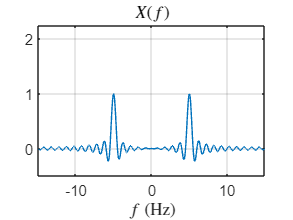

plot(f,X); grid;
axis([-15,15,-0.5,2.25]);
xlabel('$f$ (Hz)');
title('$X(f)$');

set(0,'defaultTextInterpreter','tex');